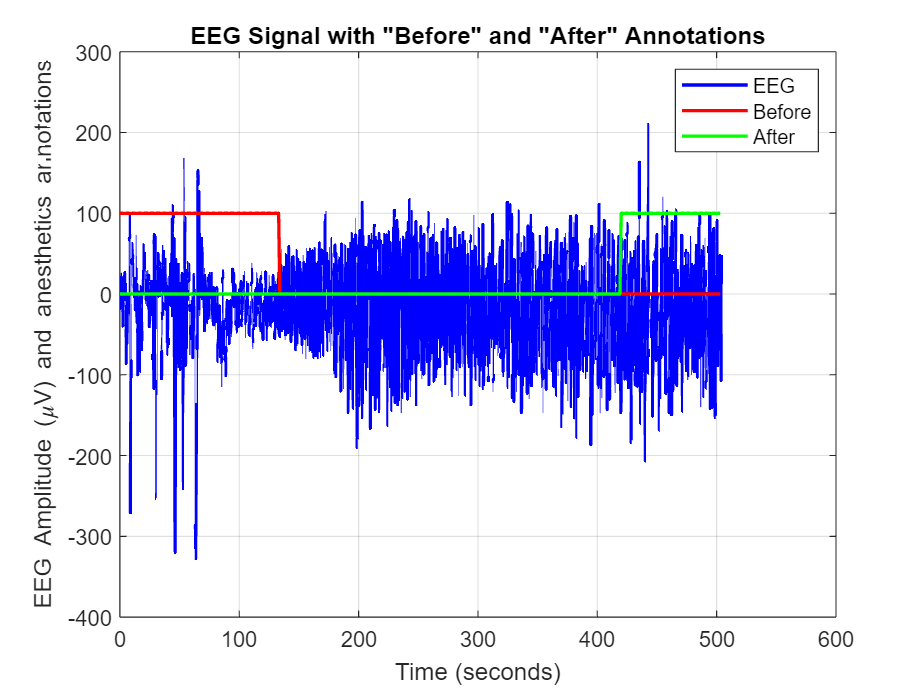

%1
% Highlighting "before anesthesia" and "after anesthesia" signals in the
% EEG signal plot
highlight_before = before * 100;
hihglight_after = after * 100;

% Plot EEG signal
figure;
plot(eeg_time, eeg_ch, 'b', 'LineWidth', 1.5);
hold on;

% Plot before and after annotations
plot(annot_time, highlight_before, 'r', 'LineWidth', 1.5);
plot(annot_time, hihglight_after, 'g', 'LineWidth', 1.5);

xlabel('Time (seconds)');
ylabel('EEG Amplitude (\muV) and anesthetics annotations');
title('EEG Signal with "Before" and "After" Annotations');

% Add legend
legend('EEG', 'Before', 'After');

% Set grid
grid on;

% Adjust axis limits if necessary
% xlim([min_time max_time]); % set min_time and max_time as needed

% Show plot
hold off;

% from the graph, 0-130s is the awaking interval
% 420-500s is the waking up interval.

%2
time_diff = diff(eeg_time);
fs_eeg = ceil(1 / mean(time_diff)); % Sampling frequency of the EEG signal

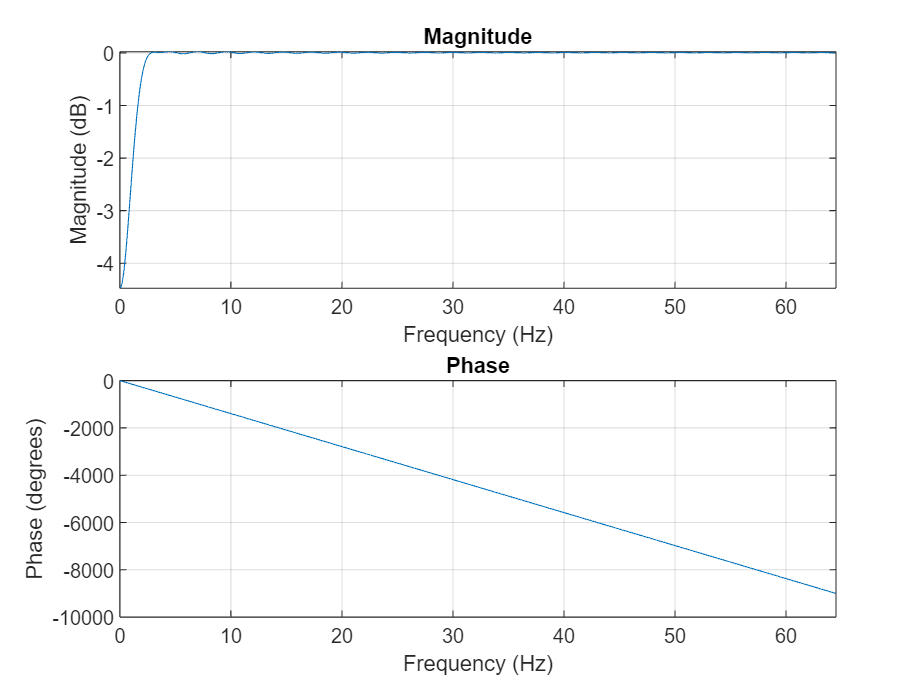

%3
% Define filter parameters
cutoff_freq = 0.5;  % Cutoff frequency
N = 100;  % Filter order 

% Design the FIR highpass filter
b = fir1(N, cutoff_freq / (fs_eeg/2), 'high');
% use FIR filter to preserve the linear phase shift

% Plot frequency response of the filter
freqz(b, 1, 1024, fs_eeg);

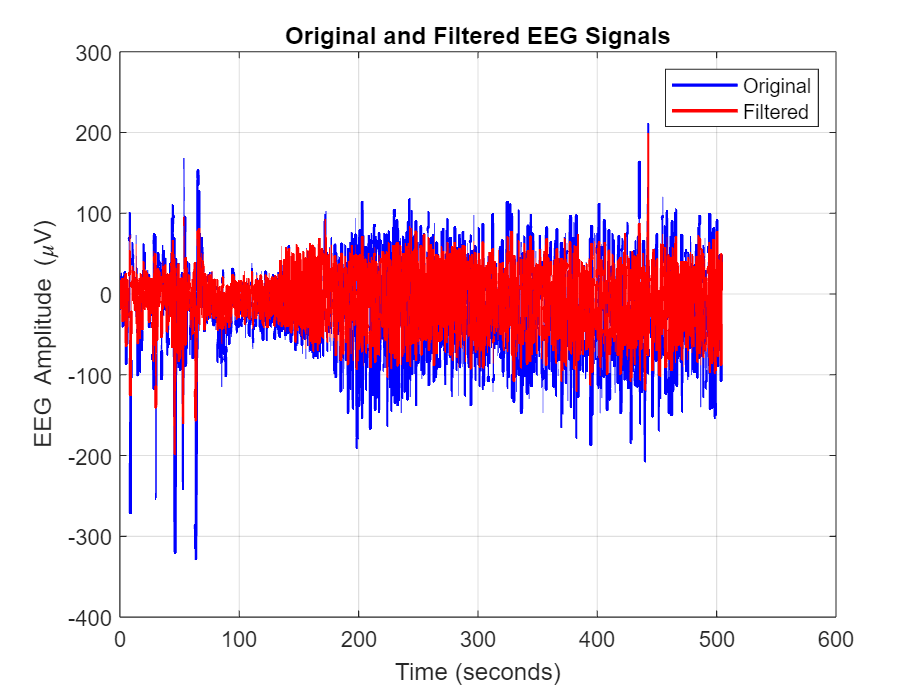

% Apply the filter to the EEG signal using filtfilt to correct for phase shifts
eeg_filtered = filtfilt(b, 1, eeg_ch);

% Plot original and filtered EEG signals
figure;
plot(eeg_time, eeg_ch, 'b', 'LineWidth', 1.5);
hold on;
plot(eeg_time, eeg_filtered, 'r', 'LineWidth', 1.5);
xlabel('Time (seconds)');
ylabel('EEG Amplitude (\muV)');
title('Original and Filtered EEG Signals');
legend('Original', 'Filtered');
grid on;

% The filtered signal shows less fluctuation compared to the original one.
% Since the filter eliminated the low-frequency components that resulted
% from movement artifact, it especially has effect when the patient were
% awaken (0-130s), and when the patien woke up (420-500s).